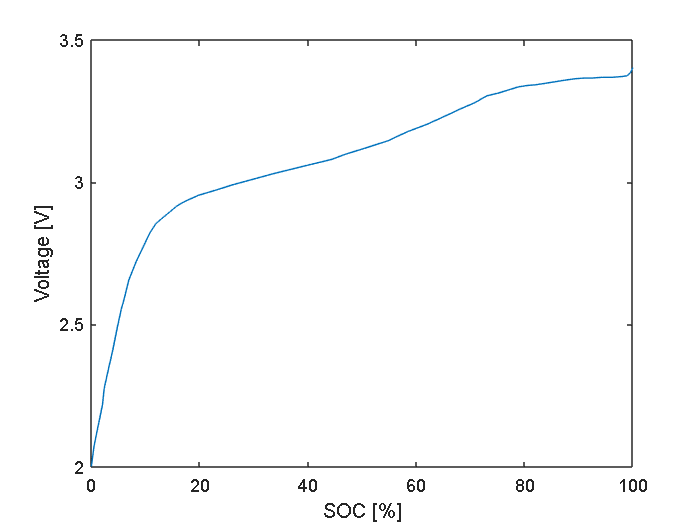

tableDchg = readtable("full_cell_cover2_discharge.csv");
cVecDchg = table2array(tableDchg(:,"capacity"));
vVecDchg = table2array(tableDchg(:,"voltage"));

SOC = 100 - cVecDchg / max(cVecDchg) * 100;
plot(SOC, vVecDchg)
ylabel("Voltage [V]")
xlabel("SOC [%]")

sampleSOCVec = 10:10:100;
current = 1.14*10; % mA/cm^2, equivalent to 5C
powerRequirement = 27.36; % mW/cm^2
fullCellArea = 4752; % cm^2

powerVec = [];

for sampleSOC = sampleSOCVec

    voltage = interp1(SOC, vVecDchg, sampleSOC);
    power = current*voltage;
    powerVec = [powerVec power];

end

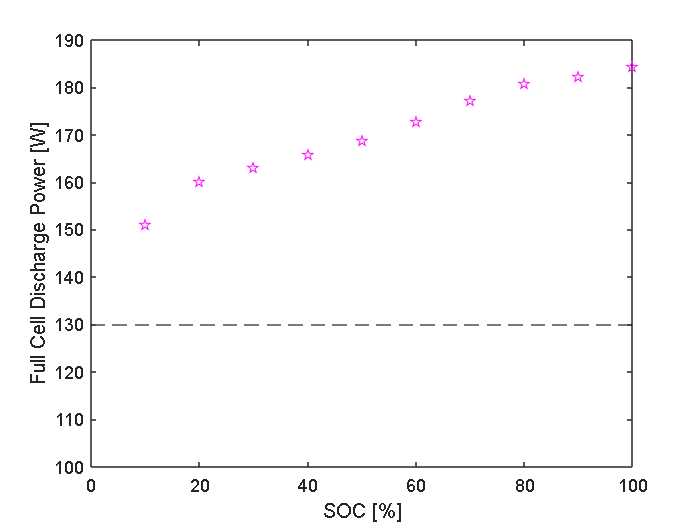

plot(sampleSOCVec, powerVec*fullCellArea/1000, 'p', color="magenta")
hold on
yline(powerRequirement*fullCellArea/1000, 'k--')
ylabel("Full Cell Discharge Power [W]")
xlabel("SOC [%]")
ylim([100,190])